## 控制参数

turbin_dist = true; %风速扰动
conv_dist = false; %变流器扰动


issim = true;% 是否仿真
time = "100";% 仿真时间


cutseries = true; % 是否切除前面不稳定的波形
steptime =80; % 切除时间

figplot = true; % 是否画图








## 仿真过程

% 仿真参数 频率：6.32Hz
var_names = ["TurOn" "ConvOn" "Freq" "Stept" "Ampl"];
var_values = ["off" "off" "6.32" "0" "3"];

if turbin_dist
    var_values(1) = "on";
    var_values(5) = "3";
end
if conv_dist
    var_values(2) = "on";
    var_values(5) = "0.1";
end




if issim ==1
    out = dosim(var_names,var_values,time);
end

Start Simulation...
历时 103.074537 秒。
Simulation End.



Macsig = out.Macsig;
Gridsig = out.Gridsig;

if cutseries ==1
    Macsig = cutserie(Macsig,steptime);
    Gridsig = cutserie(Gridsig,steptime);
end

## 计算参数

Xs=2.5596;
Xss=0.1196;
Rs=0.00706;
Rr=0.005;
Lm=2.9;
Lrr=Lm^2/(Xs-Xss);
T0=Lrr/Rr;
Wr=Macsig.Rotor_speed__wm_.Data;
s=1-Wr;

## 计算各部分的能量

t=Macsig.Electromagnetic_torque_Te__pu_.Time;
Wm=Macsig.Rotor_speed__wm_.Data;
Te=Macsig.Electromagnetic_torque_Te__pu_.Data;
Tm=Macsig.Tm.Data;

%第二部分能量
% iq=Macmeasure.Stator_measurements.Stator_current_is_q__pu_.Data;
% id=Macmeasure.Stator_measurements.Stator_current_is_d__pu_.Data;
% iq=abs(hilbert(iq));
% id=abs(hilbert(id));
% iq=0.5442-0.01084*cos(t*6.283)+0.0003878*sin(t*6.283);
% id=0.5441-0.01104*cos(t*6.283)+0.0003386*sin(t*6.238);
iq=Macsig.iqsA.Data;
id=Macsig.idsA.Data;

Eg2=0.5*Xss.*(iq.^2+id.^2);

%第三部分能量 int{Pe*d\dleta}
%--计算\delta
phiqr=Macsig.Rotor_flux_phir_q__pu_.Data;
phidr=Macsig.Rotor_flux_phir_d__pu_.Data;
phir=phidr+1j*phiqr;
%----
phiqs=Macsig.Stator_flux_phis_q__pu_.Data;
phids=Macsig.Stator_flux_phis_d__pu_.Data;
phis=phids+1j*phiqs;
%----
delta=angle(phis)-angle(phir);
for i=1:length(delta)
    if delta(i)<0
        delta(i)=delta(i)+2*pi;
    end
end
%--
Pe=(Tm).*Wm;
Eg3=intlist(Pe,delta);

%第一部分能量
% Edd=-Lm/Lrr*phiqr;
% Eqq=Lm/Lrr*phidr;
% Edd=-Lm/Lrr*abs(hilbert(phiqr));
% Eqq=Lm/Lrr*abs(hilbert(phidr));
% 
% Edd=-0.9111-0.004174*cos(t*6.266)+0.003386*sin(t*6.266);
% Eqq=0.9112+0.005309*cos(t*6.301)-0.001594*sin(t*6.301);
Edd=-Lm/Lrr*Macsig.phiqrA.Data;
Eqq=Lm/Lrr*Macsig.phidrA.Data;

%--1 储存在电感中的能量
Eg11=-0.5*1/(Xs-Xss)*(Eqq.^2+Edd.^2);
%--2 由于转差率多出的一项
Eg12=s.*T0./(Xs-Xss).*(intlist(Eqq,Edd)-intlist(Edd,Eqq));
%--3 耗散能量
Eg13=-T0/(Xs-Xss)*(intlist([0;diff(Edd)],Edd))+intlist([0;diff(Eqq)],Eqq);
%--4 相当于励磁的一项
Vqr=Macsig.VqrA.Data;
Vdr=Macsig.VdrA.Data;
Eg14=-Lm*T0/(Xs-Xss)/Lrr*(intlist(Vqr,Edd)+intlist(Vdr,Eqq));

Eg1=Eg11+Eg12+Eg13+Eg14;

Eg=Eg1+Eg2+Eg3;

## 绘制图形

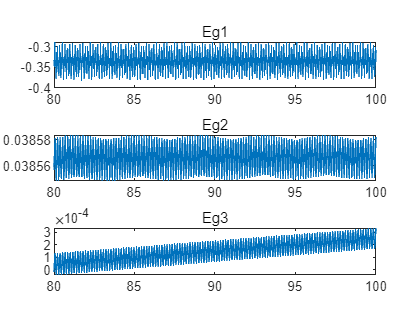

%figplot==1 绘制Eg1,Eg2,Eg3
%figplot==2 绘制Eg11,Eg12,Eg13,Eg14
if figplot==1
    figure('Name','DFIG能量函数构成')
    subplot(3,1,1)
    plot(t,Eg1)
    title('Eg1')
    subplot(3,1,2)
    plot(t,Eg2)
    title('Eg2')
    subplot(3,1,3)
    plot(t,Eg3)
    title('Eg3')
end

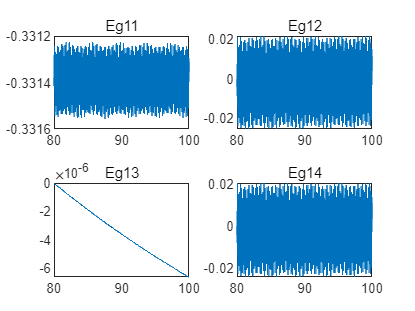


if figplot==1
    figure('Name','Eg1能量构成')
    subplot(2,2,1)
    plot(t,Eg11)
    title('Eg11')
    subplot(2,2,2)
    plot(t,Eg12)
    title('Eg12')
    subplot(2,2,3)
    plot(t,Eg13)
    title('Eg13')
    subplot(2,2,4)
    plot(t,Eg14)
    title('Eg14')
end

## 计算端口能量并比较

GP=Gridsig.SourceP.Data;
GQ=Gridsig.SourceQ.Data;
Gtheta=Gridsig.Thetaij.Data;
GVi=Gridsig.Vi.Data;
GVj=Gridsig.Vj.Data;

for i=1:length(Gtheta)
    if Gtheta(i)>5
        Gtheta(i)=Gtheta(i)-2*pi;
    end
    if Gtheta(i)<-5
        Gtheta(i)=Gtheta(i)+2*pi;
    end
end

En1=intlist(GP,Gtheta);
En2=intlist(GQ,log(GVi));
En=En1+En2;



## 函数

function out = dosim(var_names,var_values,time)
    % 调用simulink模块进行仿真
    mdl = "power_wind_dfig_avg";
    in = Simulink.SimulationInput(mdl);
    in = in.setModelParameter("StopTime",time);
    for i = 1: length(var_names)
        in = in.setBlockParameter(mdl + "/Wind Farm",var_names(i),var_values(i));
    end
    fprintf("Start Simulation...\n")
    tic
    out = sim(in);
    toc
    fprintf("Simulation End.\n")
end

function cuttered = cutserie(series_struct,steptime)
    % 裁剪仿真结果
    fields = fieldnames(series_struct);
    endtime = series_struct.(fields{1}).TimeInfo.End;
    for i = 1:length(fields)
        key= fields{i};
        series_struct.(key)= getsampleusingtime(series_struct.(key),steptime,endtime);
    end
    cuttered = series_struct;
end